## This version only for ANN test (Since it is time consuming)

## Parameters Define and Data Load

clear
clc

global nPart
global pcaDim
global person0
global person1
% In this code, the author provide a new feature process link after PCA to
% improve the identification performance
fprintf('Loading dataset...\n');

Loading dataset...


load('SmallCelebrityData.mat');
load('SmallCelebrityImageData.mat');

eps = 10^-5;

aim=[];
aim(1)=0;

nPart(1)=16;% The part number of PCA (default=16)
pcaDim(1)=500;% The dimension of PCA (default=500)

step=[];
theta=[];
step(1)=5;
theta(1)=0;%rad

person0=1;%left boundary of person index used in the experiment
person1=10;%right boundary of person index used in the experiment

K=10;% view range of nearest classifer (do classify based on K nearest number of train sample)

classLabel=unique(SmallCelebrityImageData.identity);
classNum=size(classLabel,1);

## Feature Dimension Reduction

%==========================================================================

featureNumOfPerImage=size(SmallCelebrityImageData.feature,2);% the number of features for one image
partDim = floor(featureNumOfPerImage/nPart);% The number of per image feature in each PCA part
cPts = size(SmallCelebrityImageData.identity,1);%The total number of the pictures
SmallCelebrityImageData.pcaFeature = zeros(cPts, pcaDim*nPart);% Initial the size of the PCA feature matrix
changeIndex = reshape([1:featureNumOfPerImage], [], 5)';
changeIndex = changeIndex(:);% this is a special way to shuffle the index

fprintf('Computing feature reduction...\n');

Computing feature reduction...


%=============pca======================
% The method divide the whole features of a image in to n part
for p = 1:nPart% execute PCA in each small part one by one
   partIndex = changeIndex([1 + (p-1)*partDim:p*partDim]);% Index sets of feature in each part for pca
   pcaIndex = [1 + (p-1)*pcaDim:p*pcaDim];% Index sets of feature after the pca process

   % PCA (only person's index number >k use PCA) with normalization
   X = double(SmallCelebrityImageData.feature(:,partIndex));
   X=(X-ones(size(X,1),1)*mean(X))./(ones(size(X,1),1)*std(X));% N(0,1) normalization of each image feature
   [score_mappedX, PCAmapping] = pca(X, pcaDim);
   X_PCA = bsxfun(@minus, X, PCAmapping.mean) * PCAmapping.M;

   SmallCelebrityImageData.pcaFeature(:,pcaIndex) = X_PCA;%save all part pca result in sequence into pcaFeature
end

## Classifier Construct

fprintf('Preparing dataset...\n');

Preparing dataset...


databaseIndex={};%train set
queryIndex={};%test set
% year=[2004 2005 2006 2007 2008 2009 2010 2011 2012 2013];
year=[2004 2005];

fprintf('Classifier model construct...\n');

Classifier model construct...



inta=0.001;
midLayerNodeNum=[4 6 3];
threshold=1e-6;
maxRound=1000;
alpha=0.01;
OutputActiFunc=1;

for i=1:size(year,2)
    testYear=year(1,i);
    databaseIndex{i}=find(SmallCelebrityImageData.year~=testYear & SmallCelebrityImageData.rank <=person1 & SmallCelebrityImageData.rank >= person0);
    queryIndex{i}=find(SmallCelebrityImageData.year == testYear & SmallCelebrityImageData.rank <=person1 & SmallCelebrityImageData.rank >= person0);
    
    Feature=double(SmallCelebrityImageData.pcaFeature(databaseIndex{i},:));
    Label0=SmallCelebrityImageData.identity(databaseIndex{i},:);
    
    % LBP features + PCA + ANN Classifier
    Feature=Feature';
    Label = double([Label0(:,1)==1 Label0(:,1)==2 Label0(:,1)==3 Label0(:,1)==4 Label0(:,1)==5 ...
        Label0(:,1)==6 Label0(:,1)==7 Label0(:,1)==8 Label0(:,1)==9 Label0(:,1)==10]');
    hiddenLayerSize = [50 20];
    net{i} = patternnet(hiddenLayerSize);
    net{i}.divideParam.trainRatio = 80/100;
    net{i}.divideParam.valRatio = 10/100;
    net{i}.divideParam.testRatio = 10/100;

    net{i}.trainParam.epochs = 500;%default=1000

    net{i}.layers{1}.transferFcn = 'poslin'; % this is matlab's Relu function
    net{i}.layers{2}.transferFcn = 'poslin'; 
    net{i}.layers{3}.transferFcn = 'softmax';

    net{i} = init(net{i});

    [net{i},tr] = train(net{i},normalizeL2(Feature),Label);
end

## Classify and Evaluation

fprintf('Evaluation...\n');

Evaluation...


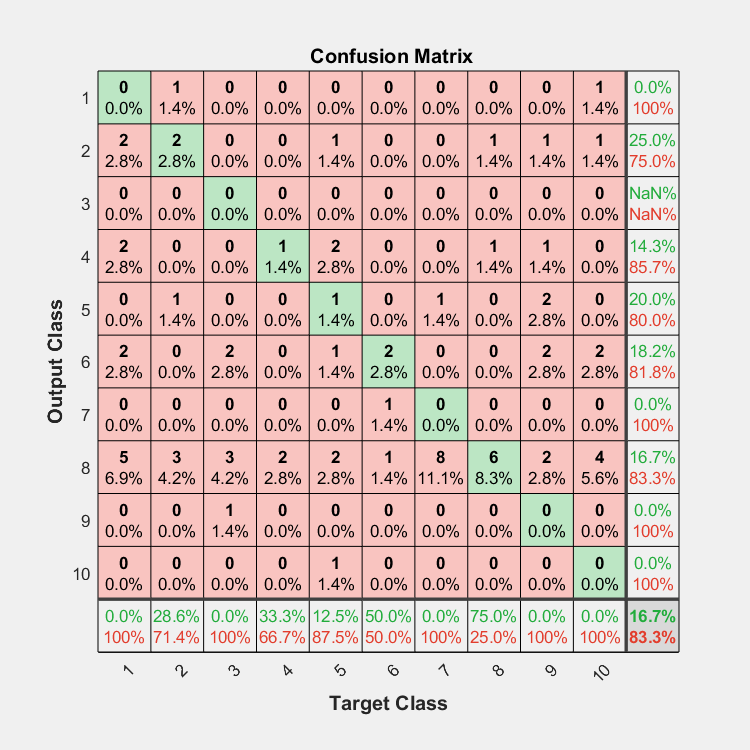

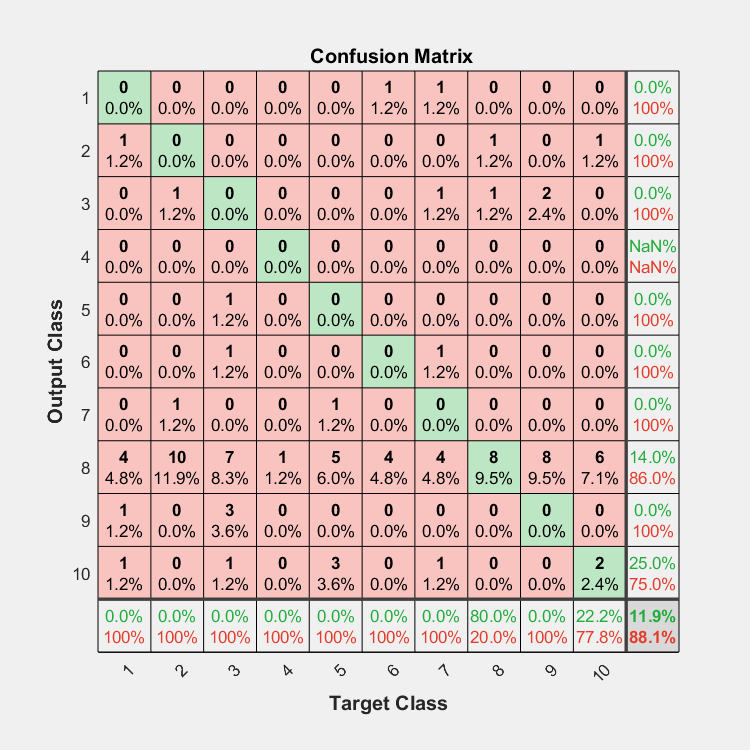


for i=1:size(year,2)
    databaseId = SmallCelebrityImageData.identity(databaseIndex{i});
    queryId = SmallCelebrityImageData.identity(queryIndex{i});
    labelID=double([queryId(:,1)==1 queryId(:,1)==2 queryId(:,1)==3 queryId(:,1)==4 queryId(:,1)==5 ...
        queryId(:,1)==6 queryId(:,1)==7 queryId(:,1)==8 queryId(:,1)==9 queryId(:,1)==10]');

    % LBP features distance matrix + ANN classifier
    Feature=double(SmallCelebrityImageData.pcaFeature(queryIndex{i},:));
    Feature=Feature';
    tstOutputs = net{i}(normalizeL2(Feature));
    seetstOutputs{i}=tstOutputs;
    [~,output]=max(tstOutputs);
    preQueryId_ANN{i}=output';
    C_ANN{i} = confusionmat(queryId,preQueryId_ANN{i});
    figure, plotconfusion(labelID,tstOutputs)
end


C_ANN_sum=zeros(classNum,classNum);

for i=1:size(year,2)
    C_ANN_sum=C_ANN_sum+C_ANN{i};
end


% ========================= Evaluation Results=========================
disp(['*****************Experiment Conclusion*******************'])

*****************Experiment Conclusion*******************



% LBP_feature+KNN_classifier
Pr_ANN=sum(diag(C_ANN_sum))/sum(sum(C_ANN_sum));
disp([' '])

disp(['Summary results of purely LBP_feature+ANN_classifier:'])

Summary results of purely LBP_feature+ANN_classifier:


disp(['Confusion Matrix:'])

Confusion Matrix:


C_ANN_sum

C_ANN_sum =      0     3     0     2     0     2     0     9     1     1
     1     2     1     0     1     0     1    13     0     0
     0     0     0     0     1     3     0    10     4     1
     0     0     0     1     0     0     0     3     0     0
     0     1     0     2     1     1     1     7     0     4
     1     0     0     0     0     2     1     5     0     0
     1     0     1     0     1     1     0    12     0     1
     0     2     1     1     0     0     0    14     0     0
     0     1     2     1     2     2     0    10     0     0
     1     2     0     0     0     2     0    10     0     2


disp(['Pr. Classification = ' num2str(Pr_ANN*100), '%'])

Pr. Classification = 14.1026%
